# 2. aet2-Klausur  2Ea/2Eb  vom  03.6.2015

## 1.

%******************************************************************************
% \details     : AET2 Aufgabe 4-54
% \autor       : Simon Burkhardt
% \file        : AET_Aufgabe_4_54.m
% \date        : 17.04.2018
% \version     : 1.0
%******************************************************************************
% p(t) = konst. visualisieren
% Bei symmetrischer Speisung und symmetrischer Last ist der Verlauf von
% p(t) = konstant.

%%

%% Hier mit den Werten für U und Z spielen:

U1m_ = 750 * exp(j*(deg2rad(-25)));
U2m_ = 750 * exp(j*(angle(U1m_)+2*pi/3));
U3m_ = 750 * exp(j*(angle(U2m_)+2*pi/3));
% compass(U1m_); hold on
% compass(U2m_);
% compass(U3m_);

Z1_ = (0);
Z3_ = (7*j);
Z2_ = (6-8*j);

%%
I1_ = U1m_ / Z1_

I1_ = Inf - Infi

I2_ = U2m_ / Z2_

I2_ = -63.6937 + 39.5994i

I3_ = U3m_ / Z3_

I3_ = -61.4546 + 87.7663i

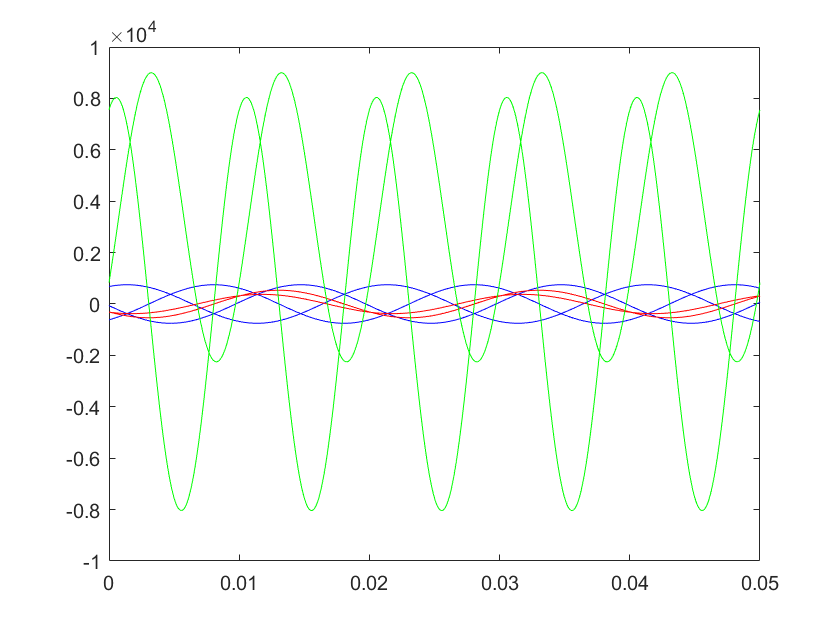


S1_ = U1m_ * I1_';
S2_ = U1m_ * I2_';
S3_ = U1m_ * I3_';

S_ = S1_+S2_+S3_;

%%
f=50; w=2*pi*f; T=1/f;
t=linspace(0, 2.5*T, 1e3);

u1t = abs(U1m_)*cos(w*t + angle(U1m_));
u2t = abs(U2m_)*cos(w*t + angle(U2m_));
u3t = abs(U3m_)*cos(w*t + angle(U3m_));

plot(t, u1t, "blue"); hold on
plot(t, u2t, "blue");
plot(t, u3t, "blue");

i1t = abs(I1_)*cos(w*t + angle(I1_));
i2t = abs(I2_)*cos(w*t + angle(I2_));
i3t = abs(I3_)*cos(w*t + angle(I3_));

plot(t, 5*i1t, "red"); hold on
plot(t, 5*i2t, "red");
plot(t, 5*i3t, "red");

p1t = u1t.*i1t;
p2t = u2t.*i2t;
p3t = u3t.*i3t;

plot(t, p1t/5, "green"); hold on
plot(t, p2t/5, "green");
plot(t, p3t/5, "green");

pt = p1t+p2t+p3t;

plot(t, pt./10, "magenta");

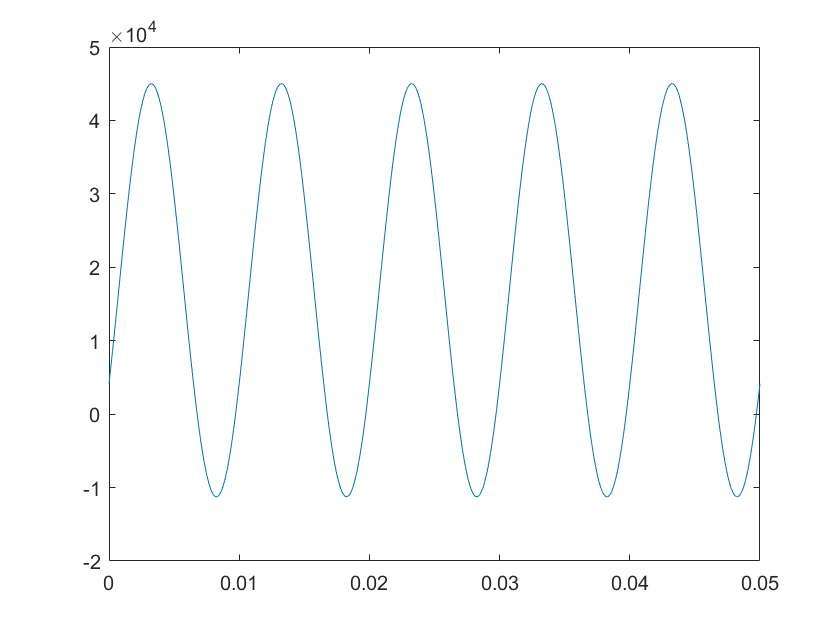


figure(2)
plot(t, p2t)

## 2.